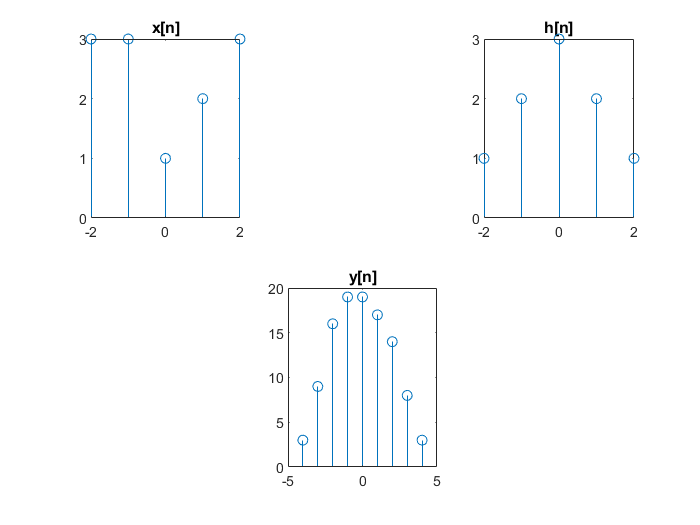

clc 
clear 
close all

o=2;p=-o:1:o;
x=zeros(size(p));
x(p==-2)=3;x(p==-1)=3;x(p==0)=1;x(p==1)=2;x(p==2)=3;
subplot(2,3,1);stem(p,x);title('x[n]');
h=zeros(size(p));
h(p==-2)=1;h(p==-1)=2;h(p==0)=3;h(p==1)=2;h(p==2)=1;
subplot(2,3,3);stem(p,h);title('h[n]');
m=length(x);n=length(h);L=m+n-1;
xe=zeros(1,L);
he=zeros(1,L);
y=he;
xe(1:m)=x;
xe(m+1:1)=0;
he(1:n)=h;
he(n+1:1)=0;
for i=1:L
    y(i)=0;
    for k=1:i
        y(i)=y(i)+he(k)*xe(i-k+1);
    end
end
v=-4:1:4;
subplot(2,3,5);stem(v,y);title('y[n]');